clear; close all;

[ProgressClassFile, ProgressClassFolder, tf] = uigetfile("F:\YuLab\Work\GPS\Data\*.mat");
if ~tf
    return;
end
ProgressClassPath = fullfile(ProgressClassFolder, ProgressClassFile);

load(ProgressClassPath);

Beh = obj.BehavTable;

FigFolder = fullfile(ProgressClassFolder, "TestFigs");
if ~isfolder(FigFolder)
    mkdir(FigFolder);
end


## Progress based on trial

n_trials = 100;

id_control = find(Beh.Label=="Control");
id_chemo = find(Beh.Label=="Chemo");

id_l_guide = find(Beh.PortCorrect==1 & Beh.Cued==0 & Beh.Guided==1);
id_r_guide = find(Beh.PortCorrect==2 & Beh.Cued==0 & Beh.Guided==1);

id_l_fill = find(Beh.PortCorrect==1 & Beh.Cued==0 & Beh.Guided==0 & Beh.Filled==1);
id_l_empty = find(Beh.PortCorrect==1 & Beh.Cued==0 & Beh.Guided==0 & Beh.Filled==0);
id_r_fill = find(Beh.PortCorrect==2 & Beh.Cued==0 & Beh.Guided==0 & Beh.Filled==1);
id_r_empty = find(Beh.PortCorrect==2 & Beh.Cued==0 & Beh.Guided==0 & Beh.Filled==0);

if ~isempty(id_chemo)
    id_l_guide = id_l_guide(id_l_guide<id_chemo(1));
    id_r_guide = id_r_guide(id_r_guide<id_chemo(1));

    id_l_fill = id_l_fill(id_l_fill<id_chemo(1));
    id_l_empty = id_l_empty(id_l_empty<id_chemo(1));
    id_r_fill = id_r_fill(id_r_fill<id_chemo(1));
    id_r_empty = id_r_empty(id_r_empty<id_chemo(1));
end

hd_l_guide = Beh.HoldDuration(id_l_guide);
hd_r_guide = Beh.HoldDuration(id_r_guide);
hd_l_fill = Beh.HoldDuration(id_l_fill);
hd_l_empty = Beh.HoldDuration(id_l_empty);
hd_r_fill = Beh.HoldDuration(id_r_fill);
hd_r_empty = Beh.HoldDuration(id_r_empty);

mt_l_guide = Beh.MovementTime(id_l_guide);
mt_r_guide = Beh.MovementTime(id_r_guide);
mt_l_fill = Beh.MovementTime(id_l_fill);
mt_l_empty = Beh.MovementTime(id_l_empty);
mt_r_fill = Beh.MovementTime(id_r_fill);
mt_r_empty = Beh.MovementTime(id_r_empty);


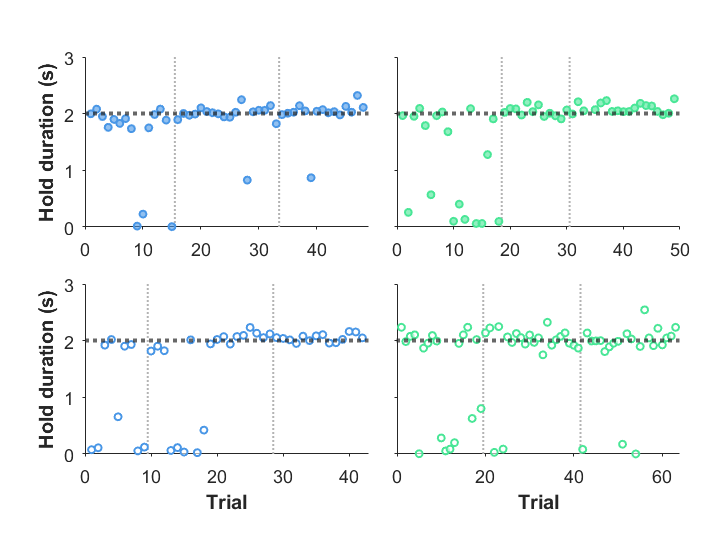


fig = figure(34); clf(34);
set(fig, 'Visible', 'on', 'Units', 'centimeters', 'Position', [5 5 12.5 9.5], 'Name', 'fill vs empty', 'Color', 'w');

%
ax_l_fill = axes(fig, 'Units', 'centimeters', 'Position', [1.5 5.5 5 3], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');

sep_l_fill = find(diff(double(Beh.SessionDate(id_l_fill)))~=0) + .5;
for i = 1:length(sep_l_fill)
    line(ax_l_fill, [sep_l_fill(i) sep_l_fill(i)], [0 3], 'LineStyle', ':', 'LineWidth', 1, 'Color', [.7 .7 .7]);
end

yline(ax_l_fill, 2, 'LineStyle', ':', 'LineWidth', 2);
scatter(ax_l_fill, 1:length(hd_l_fill), hd_l_fill, 12, ...
    'MarkerFaceColor', GPSColor.PortL, 'MarkerFaceAlpha', .6, ...
    'MarkerEdgeColor', GPSColor.PortL, 'LineWidth', 1);

ax_l_fill.YLabel.String = "Hold duration (s)";
ax_l_fill.YLabel.FontWeight = "bold";
set(ax_l_fill, 'YLim', [0 3], 'XLim', [0 length(id_l_fill)+1]);

%
ax_l_empty = axes(fig, 'Units', 'centimeters', 'Position', [1.5 1.5 5 3], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');

sep_l_empty = find(diff(double(Beh.SessionDate(id_l_empty)))~=0) + .5;
for i = 1:length(sep_l_empty)
    line(ax_l_empty, [sep_l_empty(i) sep_l_empty(i)], [0 3], 'LineStyle', ':', 'LineWidth', 1, 'Color', [.7 .7 .7]);
end

yline(ax_l_empty, 2, 'LineStyle', ':', 'LineWidth', 2);
scatter(ax_l_empty, 1:length(hd_l_empty), hd_l_empty, 12, ...
    'MarkerFaceColor', 'w', 'MarkerFaceAlpha', .6, ...
    'MarkerEdgeColor', GPSColor.PortL, 'LineWidth', 1);

ax_l_empty.YLabel.String = "Hold duration (s)";
ax_l_empty.YLabel.FontWeight = "bold";
ax_l_empty.XLabel.String = "Trial";
ax_l_empty.XLabel.FontWeight = "bold";
set(ax_l_empty, 'YLim', [0 3], 'XLim', [0 length(id_l_empty)+1]);

%
ax_r_fill = axes(fig, 'Units', 'centimeters', 'Position', [7 5.5 5 3], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');

sep_r_fill = find(diff(double(Beh.SessionDate(id_r_fill)))~=0) + .5;
for i = 1:length(sep_r_fill)
    line(ax_r_fill, [sep_r_fill(i) sep_r_fill(i)], [0 3], 'LineStyle', ':', 'LineWidth', 1, 'Color', [.7 .7 .7]);
end

yline(ax_r_fill, 2, 'LineStyle', ':', 'LineWidth', 2);
scatter(ax_r_fill, 1:length(hd_r_fill), hd_r_fill, 12, ...
    'MarkerFaceColor', GPSColor.PortR, 'MarkerFaceAlpha', .6, ...
    'MarkerEdgeColor', GPSColor.PortR, 'LineWidth', 1);

set(ax_r_fill, 'YLim', [0 3], 'XLim', [0 length(id_r_fill)+1], 'YTickLabel', []);

%
ax_r_empty = axes(fig, 'Units', 'centimeters', 'Position', [7 1.5 5 3], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');

sep_r_empty = find(diff(double(Beh.SessionDate(id_r_empty)))~=0) + .5;
for i = 1:length(sep_r_empty)
    line(ax_r_empty, [sep_r_empty(i) sep_r_empty(i)], [0 3], 'LineStyle', ':', 'LineWidth', 1, 'Color', [.7 .7 .7]);
end

yline(ax_r_empty, 2, 'LineStyle', ':', 'LineWidth', 2);
scatter(ax_r_empty, 1:length(hd_r_empty), hd_r_empty, 12, ...
    'MarkerFaceColor', 'w', 'MarkerFaceAlpha', .6, ...
    'MarkerEdgeColor', GPSColor.PortR, 'LineWidth', 1);

ax_r_empty.XLabel.String = "Trial";
ax_r_empty.XLabel.FontWeight = "bold";
set(ax_r_empty, 'YLim', [0 3], 'XLim', [0 length(id_r_empty)+1], 'YTickLabel', []);

fig_name = sprintf("Test_%s_Unguided_scatter_%s.jpg", obj.Task, obj.Subject);
fig_path = fullfile(FigFolder, fig_name);
exportgraphics(fig, fig_path, 'Resolution', 600);

## PDF of hold duration for each condition

bins = 0:.001:3;
band_width = 0.1;
n_boot = 1000;
alpha_boot = 0.05;
valid = 1;

kde_pdf = @(x) ksdensity(x, bins, 'Function', 'pdf', 'Bandwidth', band_width); % 
boot_pdf = @(x) bootci(n_boot, {kde_pdf, x}, 'type', 'cper', 'alpha', alpha_boot);

kde_cdf = @(x) ksdensity(x, bins, 'Function', 'cdf', 'Bandwidth', band_width); % 
boot_cdf = @(x) bootci(n_boot, {kde_cdf, x}, 'type', 'cper', 'alpha', alpha_boot);


id_fill = sort([id_l_fill; id_r_fill]);
id_empty = sort([id_l_empty; id_r_empty]);

hd_fill = Beh.HoldDuration(id_fill);
hd_empty = Beh.HoldDuration(id_empty);

switch valid
    case 1
        hd_fill = hd_fill(hd_fill>0.5);
        hd_empty = hd_empty(hd_empty>0.5);
        hd_l_guide = hd_l_guide(hd_l_guide>0.5);
        hd_r_guide = hd_r_guide(hd_r_guide>0.5);
end

pd_hd_l_guide = kde_pdf(hd_l_guide);
pd_hd_r_guide = kde_pdf(hd_r_guide);
pd_hd_fill = kde_pdf(hd_fill);
pd_hd_empty = kde_pdf(hd_empty);

pd_hd_fill_ci = boot_pdf(hd_fill);
pd_hd_empty_ci = boot_pdf(hd_empty);
pd_hd_l_guide_ci = boot_pdf(hd_l_guide);
pd_hd_r_guide_ci = boot_pdf(hd_r_guide);


cd_hd_l_guide = kde_cdf(hd_l_guide);
cd_hd_r_guide = kde_cdf(hd_r_guide);
cd_hd_fill = kde_cdf(hd_fill);
cd_hd_empty = kde_cdf(hd_empty);

cd_hd_fill_ci = boot_cdf(hd_fill);
cd_hd_empty_ci = boot_cdf(hd_empty);
cd_hd_l_guide_ci = boot_cdf(hd_l_guide);
cd_hd_r_guide_ci = boot_cdf(hd_r_guide);


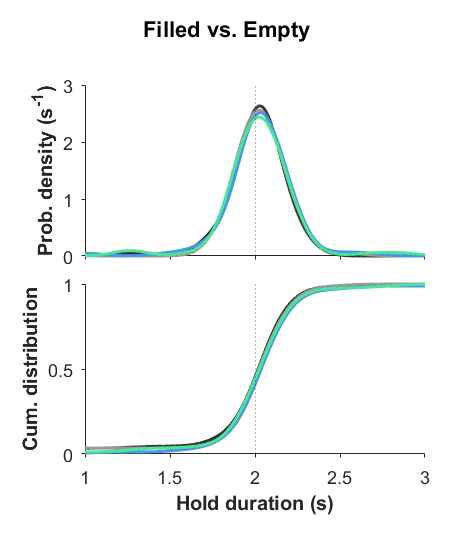

fig = figure(35); clf(35);
set(fig, 'Name', 'fill vs empty', 'Visible', 'on', 'Units', 'centimeters', 'Position', [5 5 8 9.5], 'Color', 'w');

set_fig_title(fig, "Filled vs. Empty");

%
ax_pdf = axes(fig, 'Units', 'centimeters', 'Position', [1.5 5 6 3], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');

xline(ax_pdf, 2, 'LineWidth', .5, 'LineStyle', ':');

% fill(ax_pdf, [bins flip(bins)], [pd_hd_fill_ci(1,:) flip(pd_hd_fill_ci(2,:))], 'y', ...
%     'FaceColor', GPSColor.Filled, 'FaceAlpha', 0.2, ...
%     'EdgeColor', GPSColor.Filled, 'LineStyle', '-', 'LineWidth', .5);
plot(ax_pdf, bins, pd_hd_fill, ...
    'color', GPSColor.Filled, 'linewidth', 1.5, 'LineStyle', '-');

% fill(ax_pdf, [bins flip(bins)], [pd_hd_empty_ci(1,:) flip(pd_hd_empty_ci(2,:))], 'y', ...
%     'FaceColor', GPSColor.Empty, 'FaceAlpha', 0.2, ...
%     'EdgeColor', GPSColor.Empty, 'LineStyle', '-', 'LineWidth', .5);
plot(ax_pdf, bins, pd_hd_empty, ...
    'color', GPSColor.Empty, 'linewidth', 1.5, 'LineStyle', '-');

% fill(ax_pdf, [bins flip(bins)], [pd_hd_l_guide_ci(1,:) flip(pd_hd_l_guide_ci(2,:))], 'y', ...
%     'FaceColor', GPSColor.PortL, 'FaceAlpha', 0.2, ...
%     'EdgeColor', GPSColor.PortL, 'LineStyle', '-', 'LineWidth', .5);
plot(ax_pdf, bins, pd_hd_l_guide, ...
    'color', GPSColor.PortL, 'linewidth', 1.5, 'LineStyle', '-');

% fill(ax_pdf, [bins flip(bins)], [pd_hd_r_guide_ci(1,:) flip(pd_hd_r_guide_ci(2,:))], 'y', ...
%     'FaceColor', GPSColor.PortR, 'FaceAlpha', 0.2, ...
%     'EdgeColor', GPSColor.PortR, 'LineStyle', '-', 'LineWidth', .5);
plot(ax_pdf, bins, pd_hd_r_guide, ...
    'color', GPSColor.PortR, 'linewidth', 1.5, 'LineStyle', '-');

ax_pdf.YLabel.String = "Prob. density (s^{-1})";
ax_pdf.YLabel.FontWeight = "bold";

set(ax_pdf, 'XLim', [1 3], 'XTickLabel', []);

%
ax_cdf = axes(fig, 'Units', 'centimeters', 'Position', [1.5 1.5 6 3], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');

xline(ax_cdf, 2, 'LineWidth', .5, 'LineStyle', ':');

% fill(ax_pdf, [bins flip(bins)], [cd_hd_fill_ci(1,:) flip(cd_hd_fill_ci(2,:))], 'y', ...
%     'FaceColor', GPSColor.Filled, 'FaceAlpha', 0.2, ...
%     'EdgeColor', GPSColor.Filled, 'LineStyle', '-', 'LineWidth', .5);
plot(ax_cdf, bins, cd_hd_fill, ...
    'color', GPSColor.Filled, 'linewidth', 1.5, 'LineStyle', '-');

% fill(ax_pdf, [bins flip(bins)], [cd_hd_empty_ci(1,:) flip(cd_hd_empty_ci(2,:))], 'y', ...
%     'FaceColor', GPSColor.Empty, 'FaceAlpha', 0.2, ...
%     'EdgeColor', GPSColor.Empty, 'LineStyle', '-', 'LineWidth', .5);
plot(ax_cdf, bins, cd_hd_empty, ...
    'color', GPSColor.Empty, 'linewidth', 1.5, 'LineStyle', '-');

% fill(ax_pdf, [bins flip(bins)], [cd_hd_l_guide_ci(1,:) flip(cd_hd_l_guide_ci(2,:))], 'y', ...
%     'FaceColor', GPSColor.PortL, 'FaceAlpha', 0.2, ...
%     'EdgeColor', GPSColor.PortL, 'LineStyle', '-', 'LineWidth', .5);
plot(ax_cdf, bins, cd_hd_l_guide, ...
    'color', GPSColor.PortL, 'linewidth', 1.5, 'LineStyle', '-');

% fill(ax_pdf, [bins flip(bins)], [cd_hd_r_guide_ci(1,:) flip(cd_hd_r_guide_ci(2,:))], 'y', ...
%     'FaceColor', GPSColor.PortR, 'FaceAlpha', 0.2, ...
%     'EdgeColor', GPSColor.PortR, 'LineStyle', '-', 'LineWidth', .5);
plot(ax_cdf, bins, cd_hd_r_guide, ...
    'color', GPSColor.PortR, 'linewidth', 1.5, 'LineStyle', '-');

ax_cdf.YLabel.String = "Cum. distribution";
ax_cdf.YLabel.FontWeight = "bold";
ax_cdf.XLabel.String = "Hold duration (s)";
ax_cdf.XLabel.FontWeight = "bold";

set(ax_cdf, 'XLim', [1 3]);
%
switch valid
    case 0
        fig_name = sprintf("Test_%s_Guided_vs_Unguided_HD_%s.jpg", obj.Task, obj.Subject);
    case 1
        fig_name = sprintf("Test_%s_Guided_vs_Unguided_HD_valid_%s.jpg", obj.Task, obj.Subject);
end
fig_path = fullfile(FigFolder, fig_name);
exportgraphics(fig, fig_path, 'Resolution', 600);

## PDF of movement time for each condition

bins_mt = 0:.001:1.5;
band_width = 0.1;
n_boot = 1000;
alpha_boot = 0.05;

kde_pdf_mt = @(x) ksdensity(x, bins_mt, 'Function', 'pdf', 'Bandwidth', band_width); % 
boot_pdf_mt = @(x) bootci(n_boot, {kde_pdf_mt, x}, 'type', 'cper', 'alpha', alpha_boot);


pd_mt_l_guide = kde_pdf_mt(mt_l_guide);
pd_mt_r_guide = kde_pdf_mt(mt_r_guide);
pd_mt_l_fill = kde_pdf_mt(mt_l_fill);
pd_mt_l_empty = kde_pdf_mt(mt_l_empty);
pd_mt_r_fill = kde_pdf_mt(mt_r_fill);
pd_mt_r_empty = kde_pdf_mt(mt_r_empty);

pd_mt_l_guide_ci = boot_pdf_mt(mt_l_guide);
pd_mt_r_guide_ci = boot_pdf_mt(mt_r_guide);
pd_mt_l_fill_ci = boot_pdf_mt(mt_l_fill);
pd_mt_l_empty_ci = boot_pdf_mt(mt_l_empty);
pd_mt_r_fill_ci = boot_pdf_mt(mt_r_fill);
pd_mt_r_empty_ci = boot_pdf_mt(mt_r_empty);


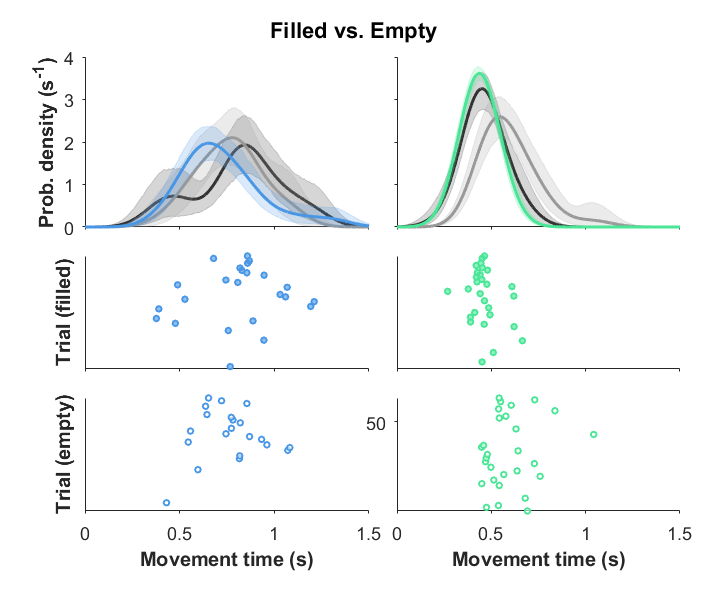

fig = figure(36); clf(36);
set(fig, 'Name', 'fill vs empty', 'Visible', 'on', 'Units', 'centimeters', 'Position', [5 5 12.5 10.5], 'Color', 'w');

set_fig_title(fig, "Filled vs. Empty");

%
ax_l_pdf = axes(fig, 'Units', 'centimeters', 'Position', [1.5 6.5 5 3], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');

fill(ax_l_pdf, [bins_mt flip(bins_mt)], [pd_mt_l_fill_ci(1,:) flip(pd_mt_l_fill_ci(2,:))], 'y', ...
    'FaceColor', GPSColor.Filled, 'FaceAlpha', .2, ...
    'EdgeColor', GPSColor.Filled, 'EdgeAlpha', .2, 'LineStyle', '-', 'LineWidth', .2);
plot(ax_l_pdf, bins_mt, pd_mt_l_fill, ...
    'color', GPSColor.Filled, 'linewidth', 1.5, 'LineStyle', '-');
fill(ax_l_pdf, [bins_mt flip(bins_mt)], [pd_mt_l_empty_ci(1,:) flip(pd_mt_l_empty_ci(2,:))], 'y', ...
    'FaceColor', GPSColor.Empty, 'FaceAlpha', .2, ...
    'EdgeColor', GPSColor.Empty, 'EdgeAlpha', .2, 'LineStyle', '-', 'LineWidth', .2);
plot(ax_l_pdf, bins_mt, pd_mt_l_empty, ...
    'color', GPSColor.Empty, 'linewidth', 1.5, 'LineStyle', '-');
fill(ax_l_pdf, [bins_mt flip(bins_mt)], [pd_mt_l_guide_ci(1,:) flip(pd_mt_l_guide_ci(2,:))], 'y', ...
    'FaceColor', GPSColor.PortL, 'FaceAlpha', .2, ...
    'EdgeColor', GPSColor.PortL, 'EdgeAlpha', .2, 'LineStyle', '-', 'LineWidth', .2);
plot(ax_l_pdf, bins_mt, pd_mt_l_guide, ...
    'color', GPSColor.PortL, 'linewidth', 1.5, 'LineStyle', '-');

ax_l_pdf.YLabel.String = "Prob. density (s^{-1})";
ax_l_pdf.YLabel.FontWeight = "bold";

set(ax_l_pdf, 'XLim', [0 1.5], 'XTickLabel', []);

%
ax_r_pdf = axes(fig, 'Units', 'centimeters', 'Position', [7 6.5 5 3], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');

fill(ax_r_pdf, [bins_mt flip(bins_mt)], [pd_mt_r_fill_ci(1,:) flip(pd_mt_r_fill_ci(2,:))], 'y', ...
    'FaceColor', GPSColor.Filled, 'FaceAlpha', .2, ...
    'EdgeColor', GPSColor.Filled, 'EdgeAlpha', .2, 'LineStyle', '-', 'LineWidth', .2);
plot(ax_r_pdf, bins_mt, pd_mt_r_fill, ...
    'color', GPSColor.Filled, 'linewidth', 1.5, 'LineStyle', '-');
fill(ax_r_pdf, [bins_mt flip(bins_mt)], [pd_mt_r_empty_ci(1,:) flip(pd_mt_r_empty_ci(2,:))], 'y', ...
    'FaceColor', GPSColor.Empty, 'FaceAlpha', .2, ...
    'EdgeColor', GPSColor.Empty, 'EdgeAlpha', .2, 'LineStyle', '-', 'LineWidth', .2);
plot(ax_r_pdf, bins_mt, pd_mt_r_empty, ...
    'color', GPSColor.Empty, 'linewidth', 1.5, 'LineStyle', '-');
fill(ax_r_pdf, [bins_mt flip(bins_mt)], [pd_mt_r_guide_ci(1,:) flip(pd_mt_r_guide_ci(2,:))], 'y', ...
    'FaceColor', GPSColor.PortR, 'FaceAlpha', .2, ...
    'EdgeColor', GPSColor.PortR, 'EdgeAlpha', .2, 'LineStyle', '-', 'LineWidth', .2);
plot(ax_r_pdf, bins_mt, pd_mt_r_guide, ...
    'color', GPSColor.PortR, 'linewidth', 1.5, 'LineStyle', '-');

set(ax_r_pdf, 'XLim', [0 1.5], 'XTickLabel', [], 'YTickLabel', []);

%
ax_l_pdf.YLim(2) = max([ax_l_pdf.YLim(2) ax_r_pdf.YLim(2)]);
ax_l_pdf.YLim(2) = (round(ax_l_pdf.YLim(2)) + ceil(ax_l_pdf.YLim(2))) / 2;
ax_r_pdf.YLim(2) = ax_l_pdf.YLim(2);

%
ax_fill_scatter = axes(fig, 'Units', 'centimeters', 'Position', [1.5 4 5 2], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');

scatter(ax_fill_scatter, mt_l_fill, 1:length(mt_l_fill), 8, ...
    'MarkerFaceColor', GPSColor.PortL, 'MarkerFaceAlpha', .6, ...
    'MarkerEdgeColor', GPSColor.PortL, 'LineWidth', 1);

ax_fill_scatter.YLabel.String = "Trial (filled)";
ax_fill_scatter.YLabel.FontWeight = "bold";

set(ax_fill_scatter, 'XLim', [0 1.5], 'XTickLabel', [], 'YLim', [1 length(mt_l_fill)], 'YTick', 0:50:length(mt_l_fill));

%
ax_r_fill_scatter = axes(fig, 'Units', 'centimeters', 'Position', [7 4 5 2], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');

xline(ax_r_fill_scatter, 2, 'LineWidth', .5, 'LineStyle', ':');

scatter(ax_r_fill_scatter, mt_r_fill, 1:length(mt_r_fill), 8, ...
    'MarkerFaceColor', GPSColor.PortR, 'MarkerFaceAlpha', .6, ...
    'MarkerEdgeColor', GPSColor.PortR, 'LineWidth', 1);

set(ax_r_fill_scatter, 'XLim', [0 1.5], 'XTickLabel', [], 'YLim', [1 length(mt_r_fill)], 'YTick', 0:50:length(mt_r_fill));

%
ax_empty_scatter = axes(fig, 'Units', 'centimeters', 'Position', [1.5 1.5 5 2], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');
scatter(ax_empty_scatter, mt_l_empty, 1:length(mt_l_empty), 8, ...
    'MarkerFaceColor', 'w', 'MarkerFaceAlpha', .6, ...
    'MarkerEdgeColor', GPSColor.PortL, 'LineWidth', 1);

ax_empty_scatter.YLabel.String = "Trial (empty)";
ax_empty_scatter.YLabel.FontWeight = "bold";
ax_empty_scatter.XLabel.String = "Movement time (s)";
ax_empty_scatter.XLabel.FontWeight = "bold";

set(ax_empty_scatter, 'XLim', [0 1.5], 'YLim', [1 length(mt_l_empty)], 'YTick', 0:50:length(mt_l_empty));

%
ax_r_empty_scatter = axes(fig, 'Units', 'centimeters', 'Position', [7 1.5 5 2], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');
scatter(ax_r_empty_scatter, mt_r_empty, 1:length(mt_r_empty), 8, ...
    'MarkerFaceColor', 'w', 'MarkerFaceAlpha', .6, ...
    'MarkerEdgeColor', GPSColor.PortR, 'LineWidth', 1);

ax_r_empty_scatter.XLabel.String = "Movement time (s)";
ax_r_empty_scatter.XLabel.FontWeight = "bold";

set(ax_r_empty_scatter, 'XLim', [0 1.5], 'YLim', [1 length(mt_r_empty)], 'YTick', 0:50:length(mt_r_empty));

fig_name = sprintf("Test_%s_Unguided_MT_%s.jpg", obj.Task, obj.Subject);
fig_path = fullfile(FigFolder, fig_name);
exportgraphics(fig, fig_path, 'Resolution', 600);